# Linear ODE Solutions

## Assume that initial state is a linear combination of eigenvectors

If $n\times n$ matrix $A$ has $n$ nonzero distinct eigenvalues, the linear differential equation


$$\dot{\mathbf{x}} = A \mathbf{x}$$


has solutions of the form


$$\mathbf{x}(t) = \sum_i q_i \mathbf{v}_i e^{\lambda_i t}$$


where $\mathbf{v}_i$ are the eigenvectors and $\lambda_i$ are the eigenvalues of $A$.

At $t=0$,


$$\mathbf{x}(0) = \sum_i q_i \mathbf{v}_i = V \mathbf{q}$$


where $\mathbf{q} = [q_1, q_2, \ldots, q_n]^\top$ and $V = [\mathbf{v}_1, \mathbf{v}_2, \ldots, \mathbf{v}_n]$.

A = [
    -1.3256 -0.5415 -0.4313;
    -0.5415 -1.4162 -0.0523;
    -0.4313 -0.0523 -0.6582;
    ];

[V, D] = eig(A);
eigvals = diag(D);
V;
q1 = 0;
q2 = 0;
q3 = -1;
q = [q1; q2; q3]

q =      0
     0
    -1



x0 = V*q

x0 =     0.5201
   -0.2349
   -0.8212



ts = (0:0.05:10)';
xv = zeros(length(q), length(ts), length(q));
for i = 1:length(q)
    xv(i,:,:) = exp(eigvals(i)*ts) * V(:,i)';
end

% this is equivalent to what the `initial` function does
xs = zeros(length(ts), length(q));
for i = 1:length(ts)
    t = ts(i);
    xs(i, :) =  V*(q .* exp(eigvals*t)); % this is just the solution equation
end

clf;
subplot(3, 1, 1)

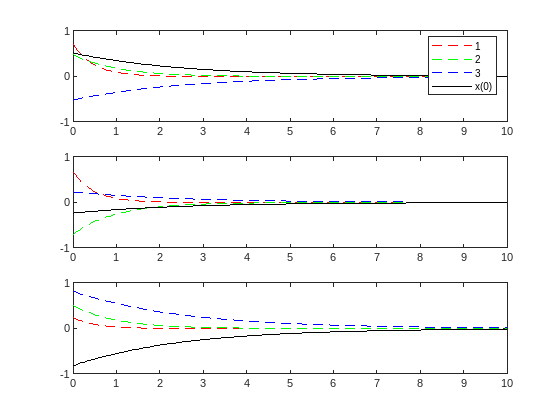

plot(ts, xv(1,:,1), 'r--', ts, xv(2,:,1), 'g--', ts, xv(3,:,1), 'b--'); ylim([-1, 1]); hold on;
plot(ts, xs(:, 1), 'k'); legend('1', '2', '3','x(0)'); hold off;
subplot(3, 1, 2)
plot(ts, xv(1,:,2), 'r--', ts, xv(2,:,2), 'g--', ts, xv(3,:,2), 'b--'); ylim([-1, 1]); hold on;
plot(ts, xs(:, 2), 'k'); hold off;
subplot(3, 1, 3)
plot(ts, xv(1,:,3), 'r--', ts, xv(2,:,3), 'g--', ts, xv(3,:,3), 'b--'); ylim([-1, 1]); hold on;
plot(ts, xs(:, 3), 'k'); hold off;

## All initial states are linear combinations of eigenvectors!

For an arbitrary initial condition, the weights, $q_i$, (which may be complex), can be calculated with


$$\mathbf{q} = V^{-1} \mathbf{x}(0)$$


x1 = 0;
x2 = -1;
x3 = 1;

x0 = [x1; x2; x3]

x0 =      0
    -1
     1


q = V\x0

q =    -0.4197
    1.2166
    0.5863


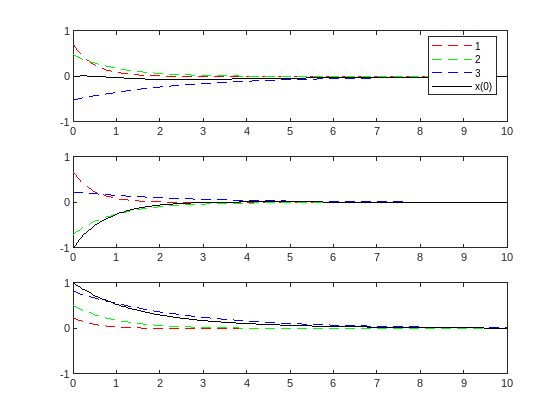


% this is equivalent to what the `initial` function does
for i = 1:length(ts)
    t = ts(i);
    xs(i, :) =  V*(q .* exp(eigvals*t)); % this is just the solution equation
end

clf;
subplot(3, 1, 1)
plot(ts, xv(1,:,1), 'r--', ts, xv(2,:,1), 'g--', ts, xv(3,:,1), 'b--'); ylim([-1, 1]); hold on;
plot(ts, xs(:, 1), 'k'); legend('1', '2', '3','x(0)'); hold off;
subplot(3, 1, 2)
plot(ts, xv(1,:,2), 'r--', ts, xv(2,:,2), 'g--', ts, xv(3,:,2), 'b--'); ylim([-1, 1]); hold on;
plot(ts, xs(:, 2), 'k'); hold off;
subplot(3, 1, 3)
plot(ts, xv(1,:,3), 'r--', ts, xv(2,:,3), 'g--', ts, xv(3,:,3), 'b--'); ylim([-1, 1]); hold on;
plot(ts, xs(:, 3), 'k'); hold off;

## Complex Eigenvalues

Now, we'll try an example with complex eigenvalues. This happens to be the longitudinal dynamics matrix of the 747.

A_lon = [
    -0.006868    0.01395         0     -32.2;
    -0.09055    -0.3151     773.98         0;
     0.0001187 -0.001026    -0.4285         0;
            0          0          1         0
];

[V, D] = eig(A_lon);
eigvals = diag(D);

u = 0;
w = -8;
q =0;
theta = 0;
x0 = [u; w; q; theta];
q = V\x0

q =   -4.0272 + 0.2578i
  -4.0272 - 0.2578i
  -0.0893 - 2.1320i
  -0.0893 + 2.1320i


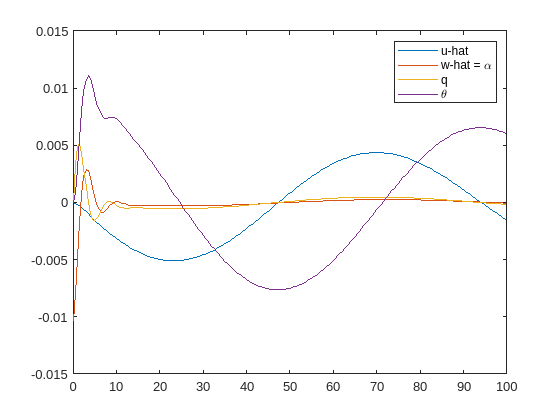


ts = (0:0.02:10)';
ts = (0:0.5:100)';

% this is equivalent to what the `initial` function does
xs = zeros(length(ts), length(q));
for i = 1:length(ts)
    t = ts(i);
    xs(i, :) =  V*(q .* exp(eigvals*t)); % this is just the solution equation
end

clf;
plot(ts, real(xs(:,1:2)/774)); hold on;
plot(ts, real(xs(:,3:4)))
legend('u-hat', 'w-hat = \alpha', 'q', '\theta')